# **Week L5: Examining Non-Linear Effects through the Manakov Equation**

The code below examines the non-linear effects in an optic fibre, in addition to attenuation and chromatic dispersion, through the solution of the Manakov equation using the split-step Fourier method

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

clearvars;

% Parameters
NSymb = 10000; % No. of symbols 
SpS = 8; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
SNR_vals = [0:1:10];
laserPw_dBm = [-20:5:20];
T = 1/(SpS*Rs); % Sampling period in s
t= [0:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 2); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = real(sourceSymbolsQPSK);
vQ_QPSK = imag(sourceSymbolsQPSK);

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1,1), "o-");
% title("Modulated Voltage")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

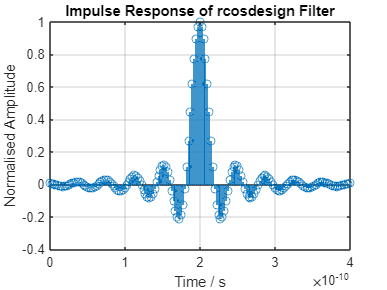

% RRC filter parameters
filterSpan = 20; % Span of RRC filter in no. of symbols
rollOff = 0.1;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)'; filterResponse = filterResponse*(1/max(filterResponse));
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of rcosdesign Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

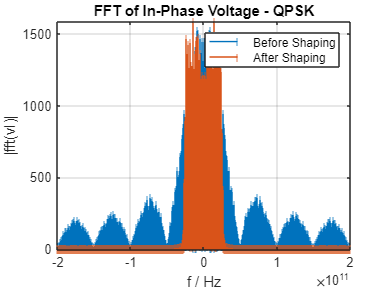


% ---------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ
vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);


% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(real(vI_QPSK_upsampled(:,1)))); % FFT of signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 2.2000e+11

### IQ Modulation

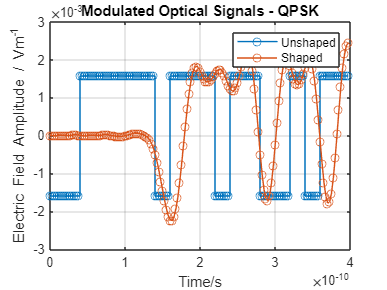

% Initialising laser parameters
lineWidth = 0;
laserPw_Lin = (1e-3)*10.^(laserPw_dBm/10);

% Modulating optical signals using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

modOpticSigQPSK = zeros(size(vI_QPSK_upsampled,1), 2, length(laserPw_dBm));
modOpticSigQPSK_shaped = zeros(size(vI_QPSK_shaped,1), 2, length(laserPw_dBm));

for i=1:length(laserPw_dBm)
    % Generating output from laser modelled as a continuous-wave source
    laserE = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, NSymb, 2); % Laser output to be used with unshaped signals
    laserE_shaped = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, samples/SpS, 2); % Laser output to be used with shaped signals

    % For QPSK:
    modOpticSigQPSK(:,:,i) = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE; % Unshaped
    modOpticSigQPSK_shaped(:,:,i) = (vI_QPSK_shaped+1i*vQ_QPSK_shaped).*laserE_shaped; % Shaped
end

% Test signals
testQPSK = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE;

% Visualising modulated optical signals
% For QSPK:
stairs(t(1:20*SpS), real(modOpticSigQPSK(1:20*SpS,1,1)), "o-");
hold on
plot(t(1:20*SpS), real(modOpticSigQPSK_shaped(1+filterSpan:filterSpan+20*SpS,1,1)), "o-");
title("Modulated Optical Signals - QPSK")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Unshaped", "Shaped")
grid on
hold off

## Optical Channel

### Adding Attenuation, CD and/or Non-Linear Effects through the NLSE

Ls = 80; % Length of span in km
Ns = 8; % No. of spans
fibreParams = struct("alpha", 0.2, "gamma", 1.3, "linkLength", Ns*Ls, "D", 17); % Fibre parameters to be used in the SSFM
stepSize = 1; % Step size for SSF method in km
CLambda = 1550e-9; % Central wavelength of optical carrier in m

% Initialising channel outputs
channelOutQPSK = zeros(size(modOpticSigQPSK));
channelOutQPSK_shaped = zeros(size(modOpticSigQPSK_shaped));

% Solving the Manakov Equation using the SSF method
for i=1:length(laserPw_dBm)
    channelOutQPSK(:,:,i) = SplitStepFourier(modOpticSigQPSK(:,:,i), SpS, Rs, CLambda, fibreParams, stepSize, 2); % Unshaped
    channelOutQPSK_shaped(:,:,i) = SplitStepFourier(modOpticSigQPSK_shaped(:,:,i), SpS, Rs, CLambda, fibreParams, stepSize, 2); % Shaped
end

% Amplfier gain
channelOutQPSK = channelOutQPSK*exp(Ns*Ls*fibreParams.alpha*log(10)/20);
channelOutQPSK_shaped = channelOutQPSK_shaped*exp(Ns*Ls*fibreParams.alpha*log(10)/20);
% -------------------------------------------------------------------------------------------

% Only adding non-linear distortion (i.e. no attenuation or CD)
% for i=1:length(laserPw_dBm)
%     channelOutQPSK(:,i) = modOpticSigQPSK(:,i); channelOutQPSK_shaped(:,i) = modOpticSigQPSK_shaped(:,i);
%     for j=1:fibreParams.linkLength
%         channelOutQPSK(:,i) = exp(-1i*stepSize*fibreParams.gamma*abs(channelOutQPSK(:,i)).^2).*channelOutQPSK(:,i);
%         channelOutQPSK_shaped(:,i) = exp(-1i*stepSize*fibreParams.gamma*abs(channelOutQPSK_shaped(:,i)).^2).*channelOutQPSK_shaped(:,i);
%     end
% end

% -------------------------------------------------------------------------------------------

### CD Compensation and Rotation Correction

% This section compensates for the added CD through the SSFM using the overlap and save method

% CD compensaation
c = 3e8; % Speed of light
N_CD = ceil(6.67*(fibreParams.D*1e-6)*(CLambda^2)*(fibreParams.linkLength*1000)*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length
N_FFT = 2^13;

voltageQPSK = zeros(size(channelOutQPSK)); voltageQPSK_shaped = zeros(size(channelOutQPSK_shaped));
for i=1:length(laserPw_dBm)
    voltageQPSK(:,:,i) = OverlapSaveCDC(channelOutQPSK(:,:,i), fibreParams.D, fibreParams.linkLength*1000, CLambda, Rs, 2, SpS, N_FFT, N_CD);
    voltageQPSK_shaped(:,:,i) = OverlapSaveCDC(channelOutQPSK_shaped(:,:,i), fibreParams.D, fibreParams.linkLength*1000, CLambda, Rs, 2, SpS, N_FFT, N_CD);
end

% Non-linear phase variation
% Leff = (1-exp(-fibreParams.alpha*log(10)*Ls*Ns/10))/(fibreParams.alpha*log(10)/10)
% phiNLI = (8/9)*(fibreParams.gamma*Leff*laserPw_Lin)*180/pi
% phiNLI_unshaped = reshape(mean(angle(voltageQPSK(:,1,:))-angle(modOpticSigQPSK(:,1,:)))*180/pi,1,length(laserPw_dBm))
% phiNLI_shaped = reshape(mean(angle(voltageQPSK_shaped(:,1,:))-angle(modOpticSigQPSK_shaped(:,1,:)))*180/pi,1,length(laserPw_dBm))

% ----------------------------------------------------------------------------------------------------------------------

% Carrier recovery

voltageQPSK_4 = voltageQPSK.^4; voltageQPSK_shaped_4 = voltageQPSK_shaped.^4;

thetaCorr = (-pi/4) + (1/4)*angle(sum(voltageQPSK_4));
thetaCorr_shaped = (-pi/4) + (1/4)*angle(sum(voltageQPSK_shaped_4));

voltageQPSK_CPR = voltageQPSK; % .*exp(-1i*thetaCorr);
voltageQPSK_shaped_CPR = voltageQPSK_shaped; % .*exp(-1i*thetaCorr_shaped);


% Computing BER after carrier recovery
BER = zeros(length(laserPw_dBm), 2); BER_shaped = zeros(length(laserPw_dBm), 2);

for i=1:length(laserPw_dBm)
    clear voltageQPSK_shaped_downsampled;
    % Downsampling
    voltageQPSK_downsampled = voltageQPSK_CPR(1:SpS:end,:,i);
    voltageQPSK_shaped_downsampled(:,1) = upfirdn(voltageQPSK_shaped_CPR(:,1,i), filterResponse, 1, SpS);
    voltageQPSK_shaped_downsampled(:,2) = upfirdn(voltageQPSK_shaped_CPR(:,2,i), filterResponse, 1, SpS);
    voltageQPSK_shaped_downsampled = voltageQPSK_shaped_downsampled(filterSpan+1:end-filterSpan,:);

    % Demodulation
    IntsQPSK = pskdemod(voltageQPSK_downsampled, 4, pi/4); IntsQPSK_shaped = pskdemod(voltageQPSK_shaped_downsampled, 4, pi/4);
    BitsQPSK = int2bit(IntsQPSK, 2); BitsQPSK_shaped = int2bit(IntsQPSK_shaped, 2);
    [~, BER(i,:)] = biterr(BitsQPSK, sourceBitsQPSK); [~, BER_shaped(i,:)] = biterr(BitsQPSK_shaped, sourceBitsQPSK);
end

BER
BER_shaped

% ---------------------------------------------------------------------------------------------------------------------

% phiNLI_CPR_unshaped = reshape(mean(angle(voltageQPSK_CPR(:,1,:))-angle(modOpticSigQPSK(:,1,:)))*180/pi,1,length(laserPw_dBm))
% phiNLI_CPR_shaped = reshape(mean(angle(voltageQPSK_shaped_CPR(:,1,:))-angle(modOpticSigQPSK_shaped(:,1,:)))*180/pi,1,length(laserPw_dBm))


% Visualising constellation before and after processing
% QPSK unshaped
plot(channelOutQPSK(:,1,1), "."); 
hold on
plot(voltageQPSK(:,1,1), "."); 
plot(voltageQPSK_CPR(:,1,1), ".");
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution after Processing (Unshaped)")
legend("Before CD comp.", "After CD comp.", "After CPR")
grid on
hold off

% QPSK shaped
plot(channelOutQPSK_shaped(:,1,1), "."); 
hold on
plot(voltageQPSK_shaped(:,1,1), "."); 
plot(voltageQPSK_shaped_CPR(:,1,1), ".");
xlabel("Real"); 
ylabel("Imaginary")
title("Symbol Distribution after Processing (Shaped)")
legend("Before CD comp.", "After CD comp.", "After CPR")
grid on
hold off

% Visualising optical signals before and after noise and attenuation

% QPSK unshaped
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1,1)), "-"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK(1:10*SpS,1,1)), "-");
plot(t(1:10*SpS), real(voltageQPSK(1:10*SpS,1,1)), "-");
plot(t(1:10*SpS), real(voltageQPSK_CPR(1:10*SpS,1,1)), "-");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("QPSK Waveforms - Unshaped")
legend("Fibre Input", "Fibre Output", "After CD comp.", "After CPR")
grid on
hold off

% QPSK shaped
plot(t(1:20*SpS), real(modOpticSigQPSK_shaped(1:20*SpS,1,1)), ""); 
hold on
plot(t(1:20*SpS), real(channelOutQPSK_shaped(1:20*SpS,1,1)), "-");
plot(t(1:20*SpS), real(voltageQPSK_shaped(1:20*SpS,1,1)), "-");
plot(t(1:20*SpS), real(voltageQPSK_shaped_CPR(1:20*SpS,1,1)), "-");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("QPSK Waveforms - Shaped")
legend("Fibre Input", "Fibre Output", "After CD comp.", "After CPR")
grid on
hold off


% Evaluating and visualising spectra at fibre output
fft_channelOut = fftshift(fft(channelOutQPSK(:,1,1))); % FFT of unshaped channel output
fft_channelOut_shaped = fftshift(fft(channelOutQPSK_shaped(:,1,1))); % FFT of shaped channel output

% stem(freqArr, abs(fft_channelOut), "|");
% hold on
% stem(freqArr_shaped, abs(fft_channelOut_shaped), "|");
% title("FFT of Channel Output");
% xlabel("f / Hz");
% ylabel("|fft|");
% legend("Unshaped", "Shaped");
% hold off
% grid on

% Testing accuracy of SSFM:

% From book:
Bref = 12.5e9 % Reference bandwidth for OSNR calculations
B_WDM = bandwidth % Bandwidth
alpha_Np = fibreParams.alpha*log(10)/10
L_eff = 1/alpha_Np % Effective Length
beta2 = fibreParams.D/0.784
F_dB = 5; F_Lin = 10^(F_dB/10) % Amplifier noise factor

c = 299792458; % Speed of light in m/s
h = 6.62607015e-34 % Plank's constant in Js

eta_SS = 8*(fibreParams.gamma^2)*(L_eff^2)*alpha_Np*asinh((pi^2)*(beta2*10^-24)*(B_WDM^2)/(2*alpha_Np))*Bref/(27*pi*(beta2*10^-24)*Rs^3)

OSNR_NLI = laserPw_Lin./(Ns*eta_SS*laserPw_Lin.^3);
OSNR_ASE = laserPw_Lin./(F_Lin*Ns*(exp(alpha_Np*Ls)-1)*h*(c/CLambda)*Bref);
OSNR_total = laserPw_Lin./((Ns*eta_SS*laserPw_Lin.^3) + (F_Lin*Ns*(exp(alpha_Np*Ls)-1)*h*(c/CLambda)*Bref));

plot(laserPw_dBm, 10*log10(OSNR_NLI), "-o")
hold on
plot(laserPw_dBm, 10*log10(OSNR_ASE), "-o")
plot(laserPw_dBm, 10*log10(OSNR_total), "-o")
xlabel("Tranmit Power / dBm")
ylabel("OSNR")
legend("Only NLI", "Only ASE", "NLI+ASE")
grid on
hold off

% Debugging addition of Non-Linear Noise 

laserPw_Lin
sigPw = mean(abs(modOpticSigQPSK(:,1,:)).^2 + abs(modOpticSigQPSK(:,2,:)).^2); sigPw = reshape(sigPw,1,length(sigPw),1)
sigPw_shaped = mean(abs(modOpticSigQPSK_shaped(:,1,:)).^2 + abs(modOpticSigQPSK_shaped(:,2,:)).^2); sigPw_shaped = reshape(sigPw_shaped,1,length(sigPw_shaped),1)

% Evaluating non-linear noise power
nonLinearNoise = voltageQPSK_CPR-modOpticSigQPSK; 
nonLinearNoise_shaped = voltageQPSK_shaped_CPR-modOpticSigQPSK_shaped;

nonLinearNoisePw = mean(abs(nonLinearNoise(:,1,:)).^2 + abs(nonLinearNoise(:,2,:)).^2); nonLinearNoisePw = reshape(nonLinearNoisePw,1,length(laserPw_dBm),1)
nonLinearNoisePw_shaped = mean(abs(nonLinearNoise_shaped(:,1,:)).^2 + abs(nonLinearNoise_shaped(:,2,:)).^2); nonLinearNoisePw_shaped = reshape(nonLinearNoisePw_shaped,1,length(laserPw_dBm),1)

% Estimating SNR using manually evaluated signal and noise powers
nonLinearSNR_manual = sigPw./nonLinearNoisePw
nonLinearSNR_shaped_manual = sigPw_shaped./nonLinearNoisePw_shaped

% Visualing simulated SNR variation
plot(laserPw_dBm, 10*log10(OSNR_NLI), "-o")
hold on
plot(laserPw_dBm, 10*log10(nonLinearSNR_manual*Rs/Bref), "-o");
plot(laserPw_dBm, 10*log10(nonLinearSNR_shaped_manual*Rs/Bref), "-o");
xlabel("Laser Power / dBm");
ylabel("OSNR / dB");
title("Variation of OSNR with Laser Power");
legend("GN Model", "Unshaped", "Shaped")
grid on
hold off

% Adding ASE noise
vs = 193.1e12; % Signal frequency

ASENoisePw = F_Lin*Ns*(exp(alpha_Np*Ls)-1)*h*vs*Bref;
OSNR_ASE_sim = laserPw_Lin/ASENoisePw;
SNR_ASE_sim = 10*log10(OSNR_ASE_sim*Bref/Rs);

channelOutQPSK_ASE = zeros(size(modOpticSigQPSK)); channelOutQPSK_shaped_ASE = zeros(size(modOpticSigQPSK_shaped));
for i=1:length(laserPw_dBm)
    channelOutQPSK_ASE(:,:,i) = awgn(modOpticSigQPSK(:,:,i), convertSNR(SNR_ASE_sim(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
    channelOutQPSK_shaped_ASE(:,:,i) = awgn(modOpticSigQPSK_shaped(:,:,i), convertSNR(SNR_ASE_sim(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
end

ASENoise = channelOutQPSK_ASE-modOpticSigQPSK; 
ASENoise_shaped = channelOutQPSK_shaped_ASE-modOpticSigQPSK_shaped;

ASENoisePw = mean(abs(ASENoise(:,1,:)).^2 + abs(ASENoise(:,2,:)).^2); ASENoisePw = reshape(ASENoisePw,1,length(laserPw_dBm),1)
ASENoisePw_shaped = mean(abs(ASENoise_shaped(:,1,:)).^2 + abs(ASENoise_shaped(:,2,:)).^2); ASENoisePw_shaped = reshape(ASENoisePw_shaped,1,length(laserPw_dBm),1)

ASENoiseSNR_manual = sigPw./ASENoisePw;
ASENoiseSNR_shaped_manual = sigPw_shaped./ASENoisePw_shaped;

plot(laserPw_dBm, 10*log10(OSNR_ASE), "-o")
hold on
plot(laserPw_dBm, 10*log10(ASENoiseSNR_manual*Rs/Bref), "-o");
plot(laserPw_dBm, 10*log10(ASENoiseSNR_shaped_manual*Rs/Bref), "-o");
xlabel("Laser Power / dBm");
ylabel("OSNR / dB");
title("Variation of OSNR with Laser Power");
legend("GN Model", "Unshaped", "Shaped")
grid on
hold off

% Adding NLI through SSFM and ASE Noise

channelOutQPSK_fin = zeros(size(modOpticSigQPSK)); channelOutQPSK_shaped_fin = zeros(size(modOpticSigQPSK_shaped));
for i=1:length(laserPw_dBm)
    channelOutQPSK_fin(:,:,i) = awgn(voltageQPSK_CPR(:,:,i), convertSNR(SNR_ASE_sim(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
    channelOutQPSK_shaped_fin(:,:,i) = awgn(voltageQPSK_shaped_CPR(:,:,i), convertSNR(SNR_ASE_sim(i),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured');
end

FinalNoise = channelOutQPSK_fin-modOpticSigQPSK; 
FinalNoise_shaped = channelOutQPSK_shaped_fin-modOpticSigQPSK_shaped;

FinalNoisePw = mean(abs(FinalNoise(:,1,:)).^2 + abs(FinalNoise(:,2,:)).^2); FinalNoisePw = reshape(FinalNoisePw,1,length(laserPw_dBm),1)
FinalNoisePw_shaped = mean(abs(FinalNoise_shaped(:,1,:)).^2 + abs(FinalNoise_shaped(:,2,:)).^2); FinalNoisePw_shaped = reshape(FinalNoisePw_shaped,1,length(laserPw_dBm),1)

FinalNoiseSNR_manual = sigPw./FinalNoisePw;
FinalNoiseSNR_shaped_manual = sigPw_shaped./FinalNoisePw_shaped;

plot(laserPw_dBm, 10*log10(OSNR_total), "-o")
hold on
plot(laserPw_dBm, 10*log10(FinalNoiseSNR_manual*Rs/Bref), "-o");
plot(laserPw_dBm, 10*log10(FinalNoiseSNR_shaped_manual*Rs/Bref), "-o");
xlabel("Laser Power / dBm");
ylabel("OSNR / dB");
title("Variation of OSNR with Laser Power");
legend("GN Model", "Unshaped", "Shaped")
grid on
hold off